# 傅里叶变换工程化频率点频率验证仿真

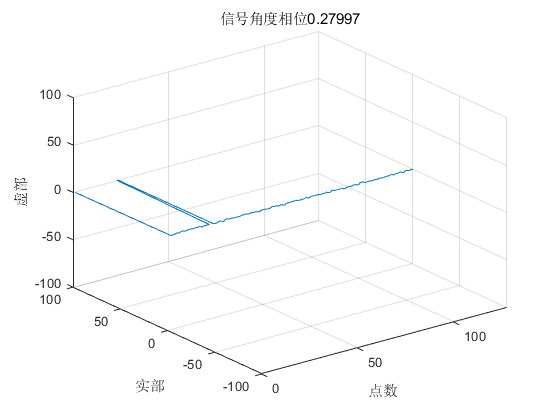

fs = 128e6;                 %信号表达频率
f = 22000000;
T = 1e-5;                   %信号持续时间
nfft = 128;
sig = rt.exp_wave(T,0,fs) + rt.exp_wave(T,f,fs);
sig = sig + 0.05.*rt.randn_complex(size(sig));

%----------------------------------------------------------
%   用零相位滤波器模拟通道特性
%----------------------------------------------------------
%   零相位滤波器
%----------------------------------------------------------
LP = designfilt('lowpassfir',...
                'PassbandFrequency', 60,...
                'StopbandFrequency', 64,...
                'PassbandRipple', 1,...
                'StopbandAttenuation', 60,...
                'SampleRate', 128);
sig = filtfilt(LP,sig);

%----------------------------------------------------------
%   常规滤波器
%----------------------------------------------------------
% LP = design_filter;
% sig = filter(LP,sig);

%----------------------------------------------------------
sig_f = fft(sig,nfft,1);
db_f = mag2db(abs(sig_f));

%----------------------------------------------------------
%   信号相位影响
%----------------------------------------------------------
figure(3);
rt.p3(sig_f);axis([0 128 -100 100 -100 100])
title(['信号角度相位' num2str(rad2deg(angle(max(sig_f))))])